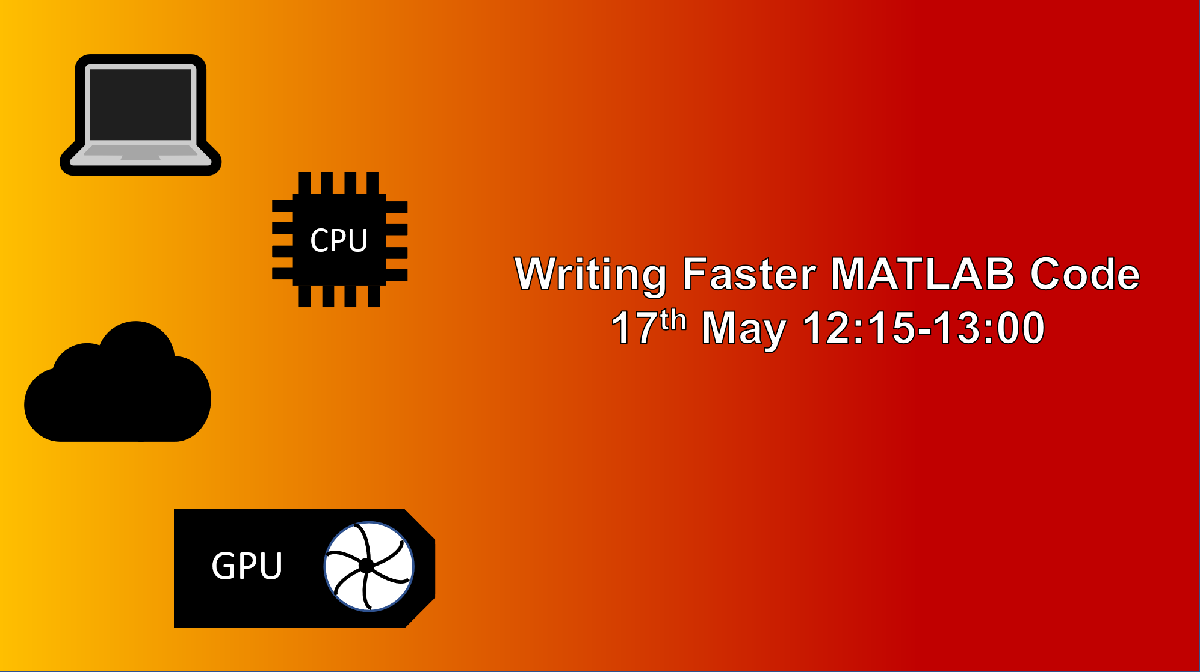

# Zoom Poll

The Zoom poll will be launched now.

# Techniques

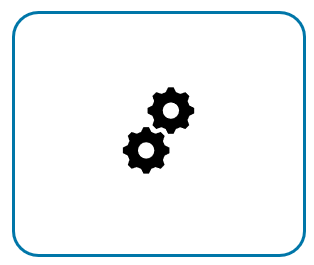

## Best Coding Practices

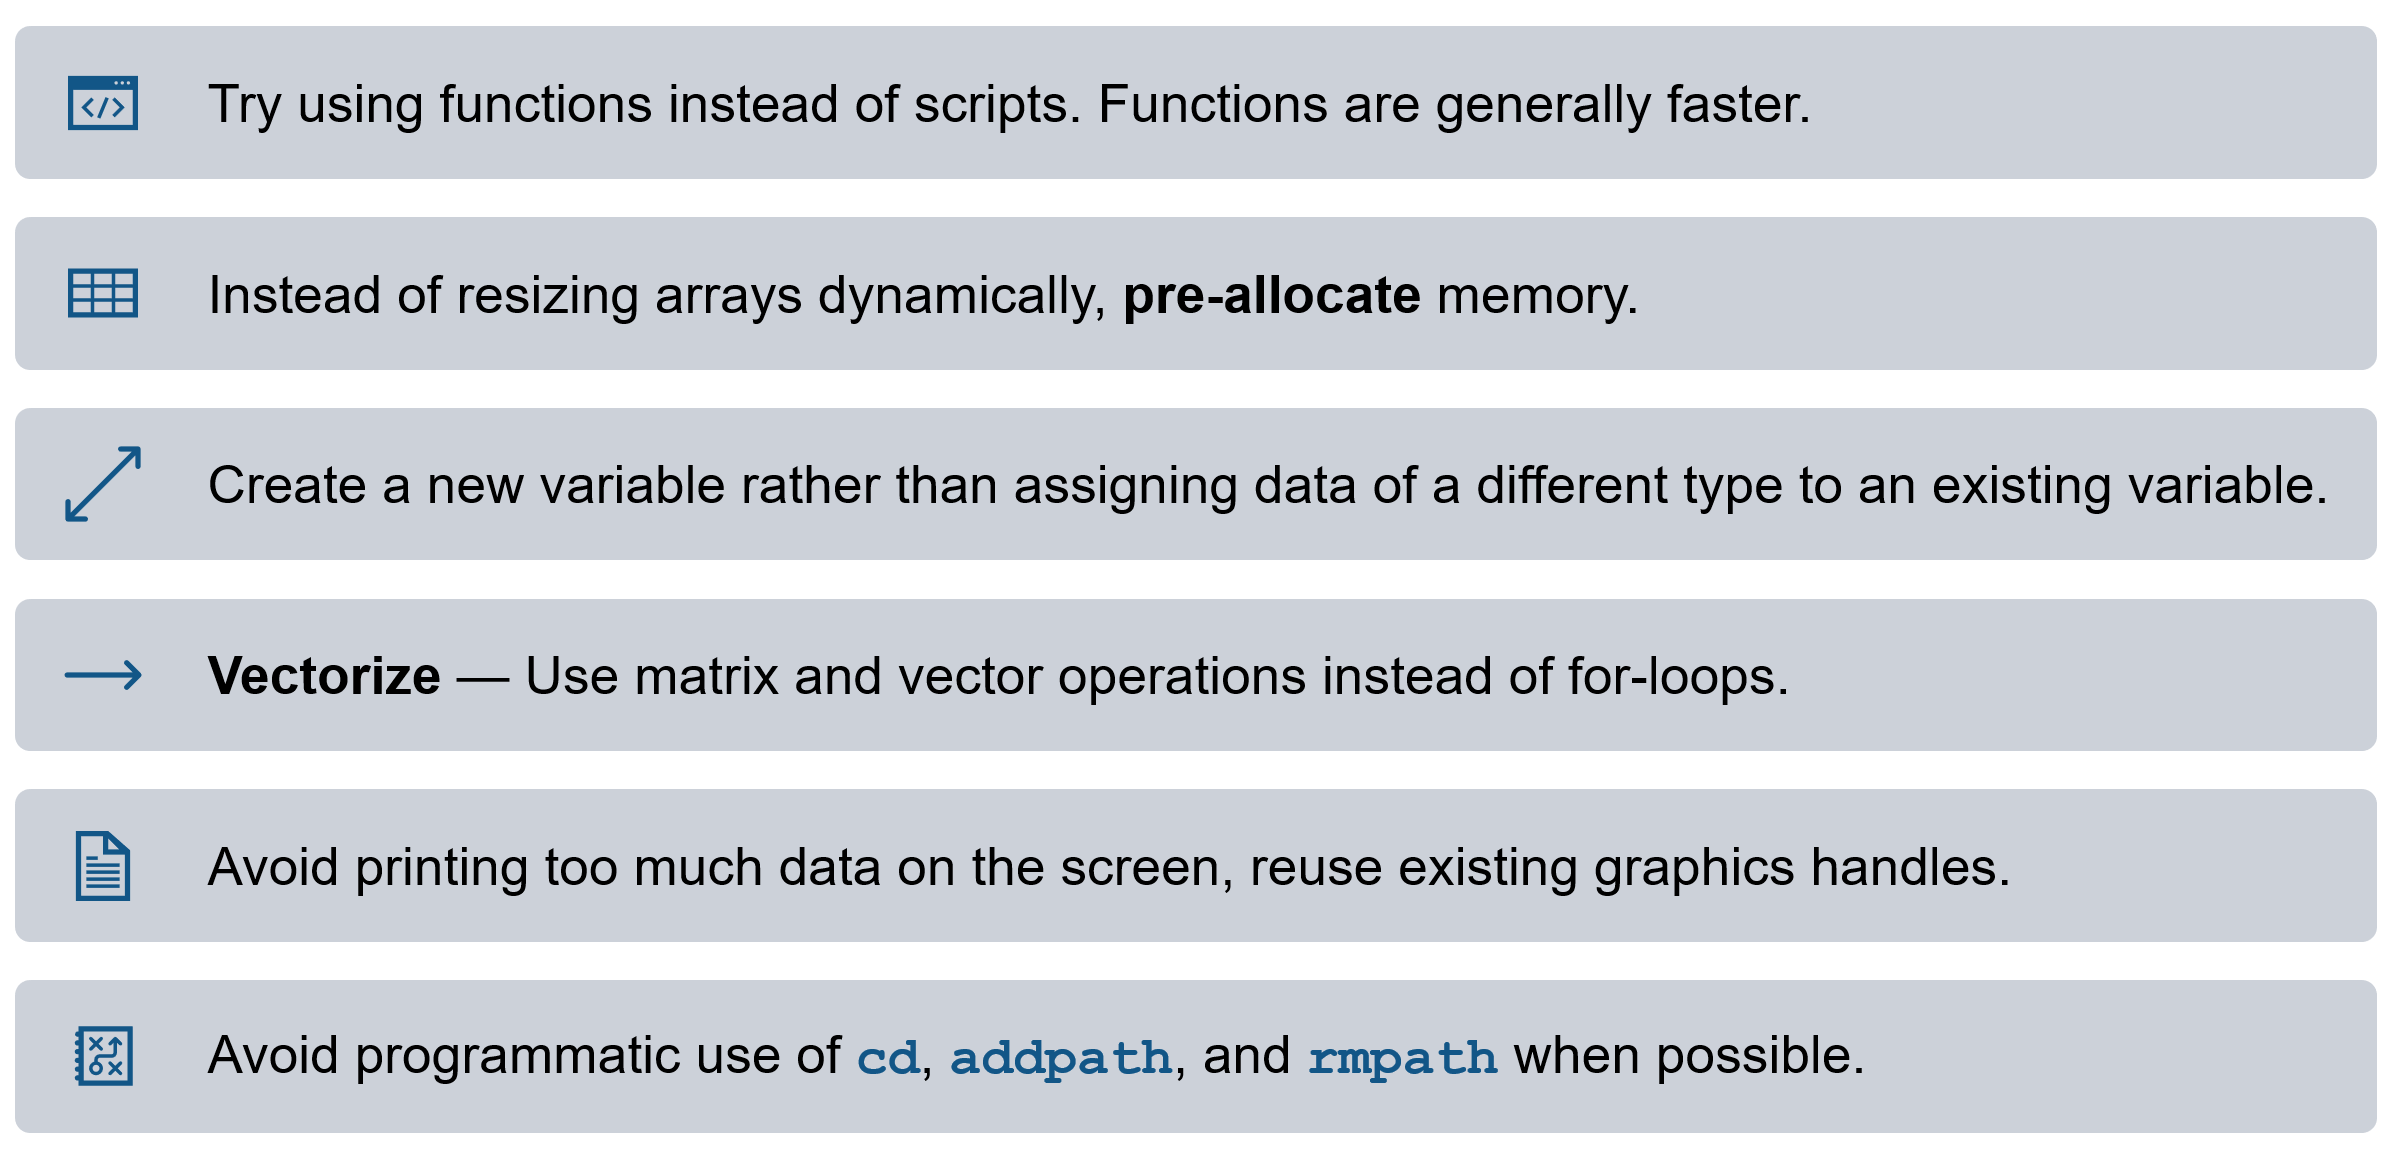

## **MATLAB code analyzer **

The Code Analyzer in the MATLAB Editor checks your code while you are writing it. The Code Analyzer identifies potential problems and recommends modifications to maximize performance.

tic
i = 0;
y = [];
for t = 0:.01:1e4
    i = i + 1;
    y(i) = sin(t);
end
plainTime = toc

plainTime =    0.278389800000000


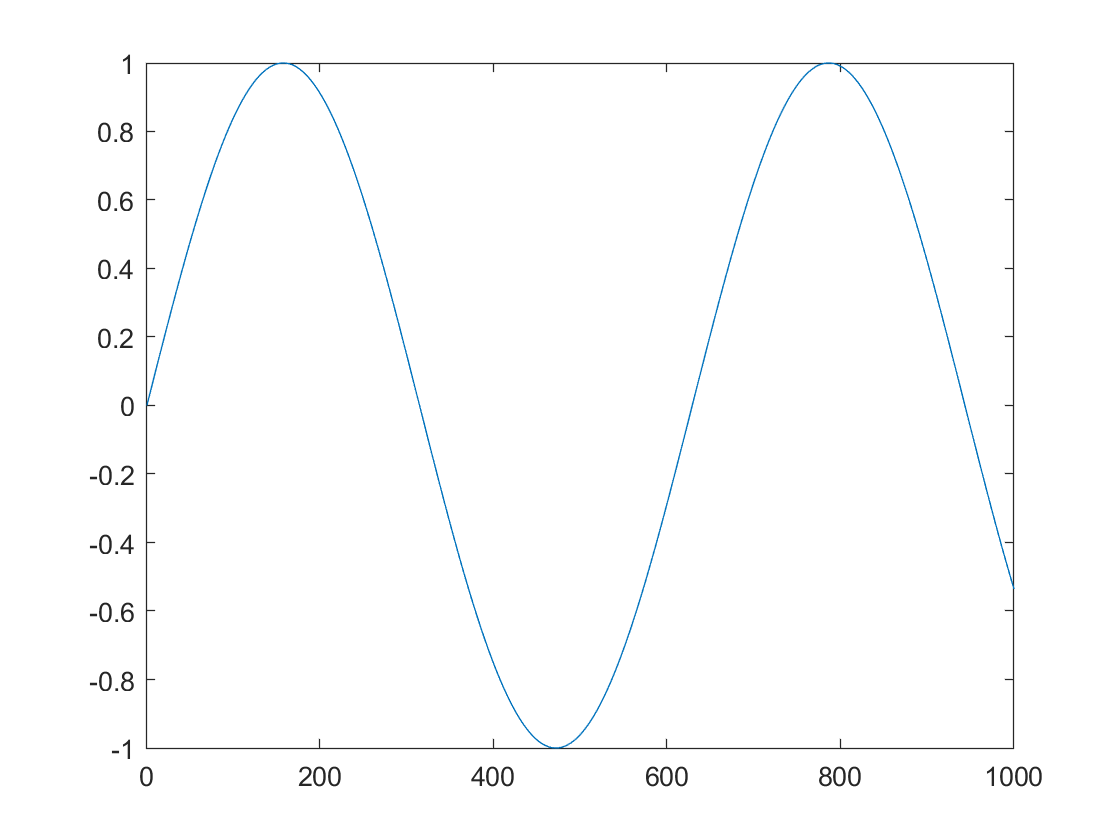

figure
plot(y(1:1e3))

## **Memory preallocation **

With preallocation, you initialize an array using the final size required for that array. Preallocation helps you avoid dynamically resizing arrays, particularly when code contains for and while loops.

tic
i = 0;
y = zeros(size(0:.01:1e4));
for t = 0:.01:1e4
    i = i + 1;
    y(i) = sin(t);
end
prealTime = toc

prealTime =    0.066180800000000


fprintf('Speedup factor of %f',plainTime/prealTime)

Speedup factor of 4.206504

## **Vectorization**

Vectorization is the process of converting code from using loops to using matrix and vector operations.

tic
t = 0:.01:1e4;
y = sin(t);
vecTime = toc

vecTime =    0.050234800000000


fprintf('Speedup factor of %f',plainTime/vecTime)

Speedup factor of 5.541772

This code is also much more readable!

## Profiler 

The Profiler shows where your code is spending its time. It provides a report summarizing the execution of your code, including the list of all functions called, the number of times each function was called, and the total time spent within each function. The Profiler also provides timing information about each function, such as which lines of code use the most processing time. This lets you find bottlenecks and streamline your serial code. 

profile on
slow_code
profile viewer

# Parallel Computing

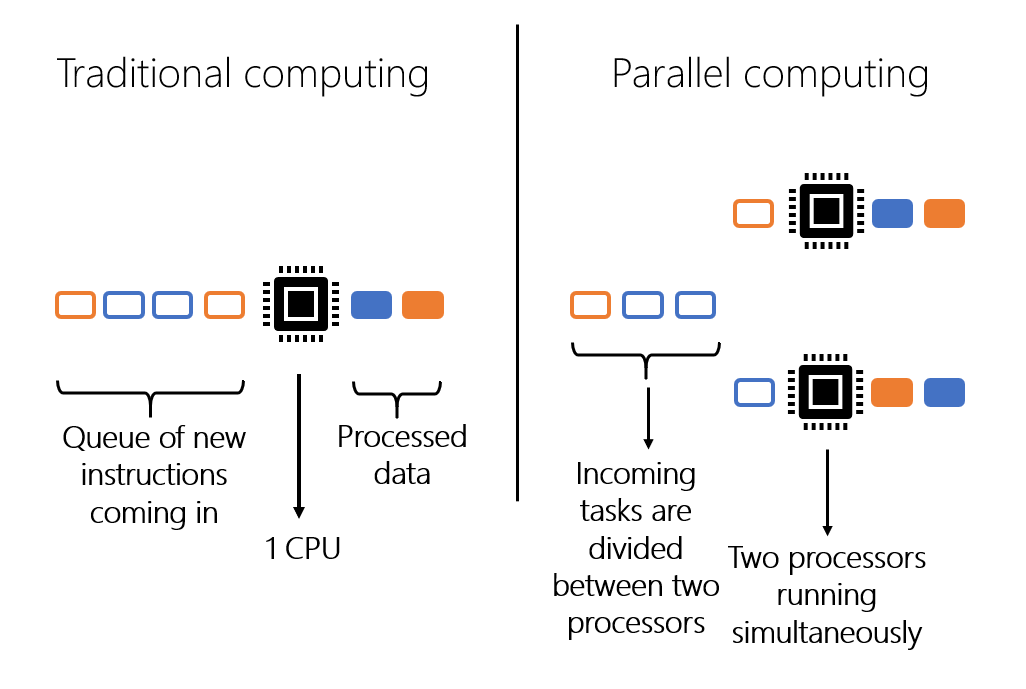

With MATLAB you can parallelize your applications without extensively changing your code. 

The **Parallel Computing Toolbox** provides the ability to distribute MATLAB code across multiple MATLAB processes.

Parallelization is beneficial only if computations take a lot of time or we have big data to deal with. Not everything is parallelizable!

### How to start a parallel pool

[https://www.mathworks.com/help/parallel-computing/run-code-on-parallel-pools.html](https://www.mathworks.com/help/parallel-computing/run-code-on-parallel-pools.html)

1) By default, a parallel pool starts automatically when needed by certain parallel language features. Many functions can automatically start a parallel pool.

`2)`Control the Parallel Pool from the MATLAB Desktop: You can use the parallel status indicator in the lower left corner of the MATLAB desktop to start a parallel pool manually.

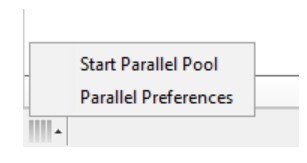

3) Programming Interface: You can start and stop a parallel pool programmatically by using default settings or specifying alternatives.

## How to parallelize MATLAB code?

### 1) Parallel-enabled toolboxes

Many functions in MATLAB allow for parallel computing, see the list [here](https://mathworks.com/help/referencelist.html?type=function&capability=parallelautosupport) and [here](https://mathworks.com/products/parallel-computing/parallel-support.html). When you use this function, you can invoke parallel processing by specifying

### 2) Parallel programming constructs. 

If you want a bit more control, then Parallel Computing Toolbox adds some parallel keywords into the MATLAB language.  An example of this is Parfor or batch commands.

#### parfor

`parfor `splits the execution of f`or`-loop iterations over the workers in a parallel pool.

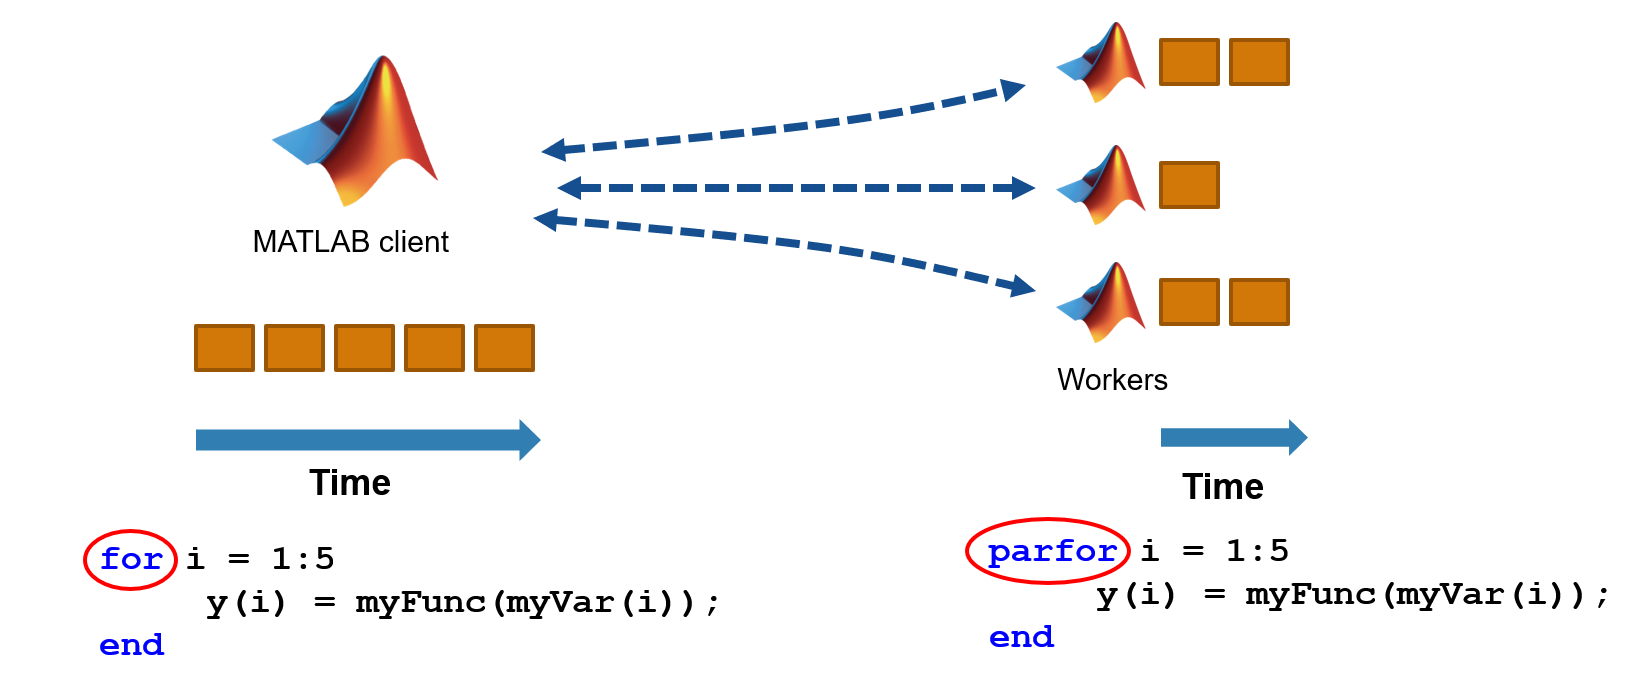

#### Examples

Simple example of using parfor

tic
for i = 1:10
    pause(1)
    disp(i)
end
toc

tic
parfor i = 1:10
    pause(1)
    disp(i)
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



toc

Elapsed time is 10.139849 seconds.


Image processing

BCCD Dataset is a small-scale dataset for blood cells detection. This dataset contains images of blood cells of 4 different cell types: Eosinophil, Lymphocyte, Monocyte, and Neutrophil. 

Data preparation is important to use machine learning. We need to make preparation data for recognition of abnormalities in blood cells on medical images.

im_dir = 'SpeedingUpMATLABCode\JPEGImages'; %Set your folder
imds = imageDatastore(im_dir,'FileExtensions', '.jpg');
figure
montage(imds)

     1

     2

     6

     4

     5

     3

     7

     8

     9

    10



**1 CPU**

N = length(imds.Files)

Elapsed time is 5.448338 seconds.


BWs = uint8(zeros(480,480,N));
avg = fspecial('average'); % Create an averaging filter
tic
for i = 1:N
    I = rgb2gray(readimage(imds,1));
    Ires = imresize(I,[480 480]);

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Faster MATLAB\SpeedingUpMATLABCode\JPEGImages\BloodImage_00000.jpg';
                              ' ...\Faster MATLAB\SpeedingUpMATLABCode\JPEGImages\BloodImage_00001.jpg';
                              ' ...\Faster MATLAB\SpeedingUpMATLABCode\JPEGImages\BloodImage_00002.jpg'
                               ... and 361 more
                              }
                     Folders: {
                              ' ...\Seminars\Faster MATLAB\SpeedingUpMATLABCode\JPEGImages'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


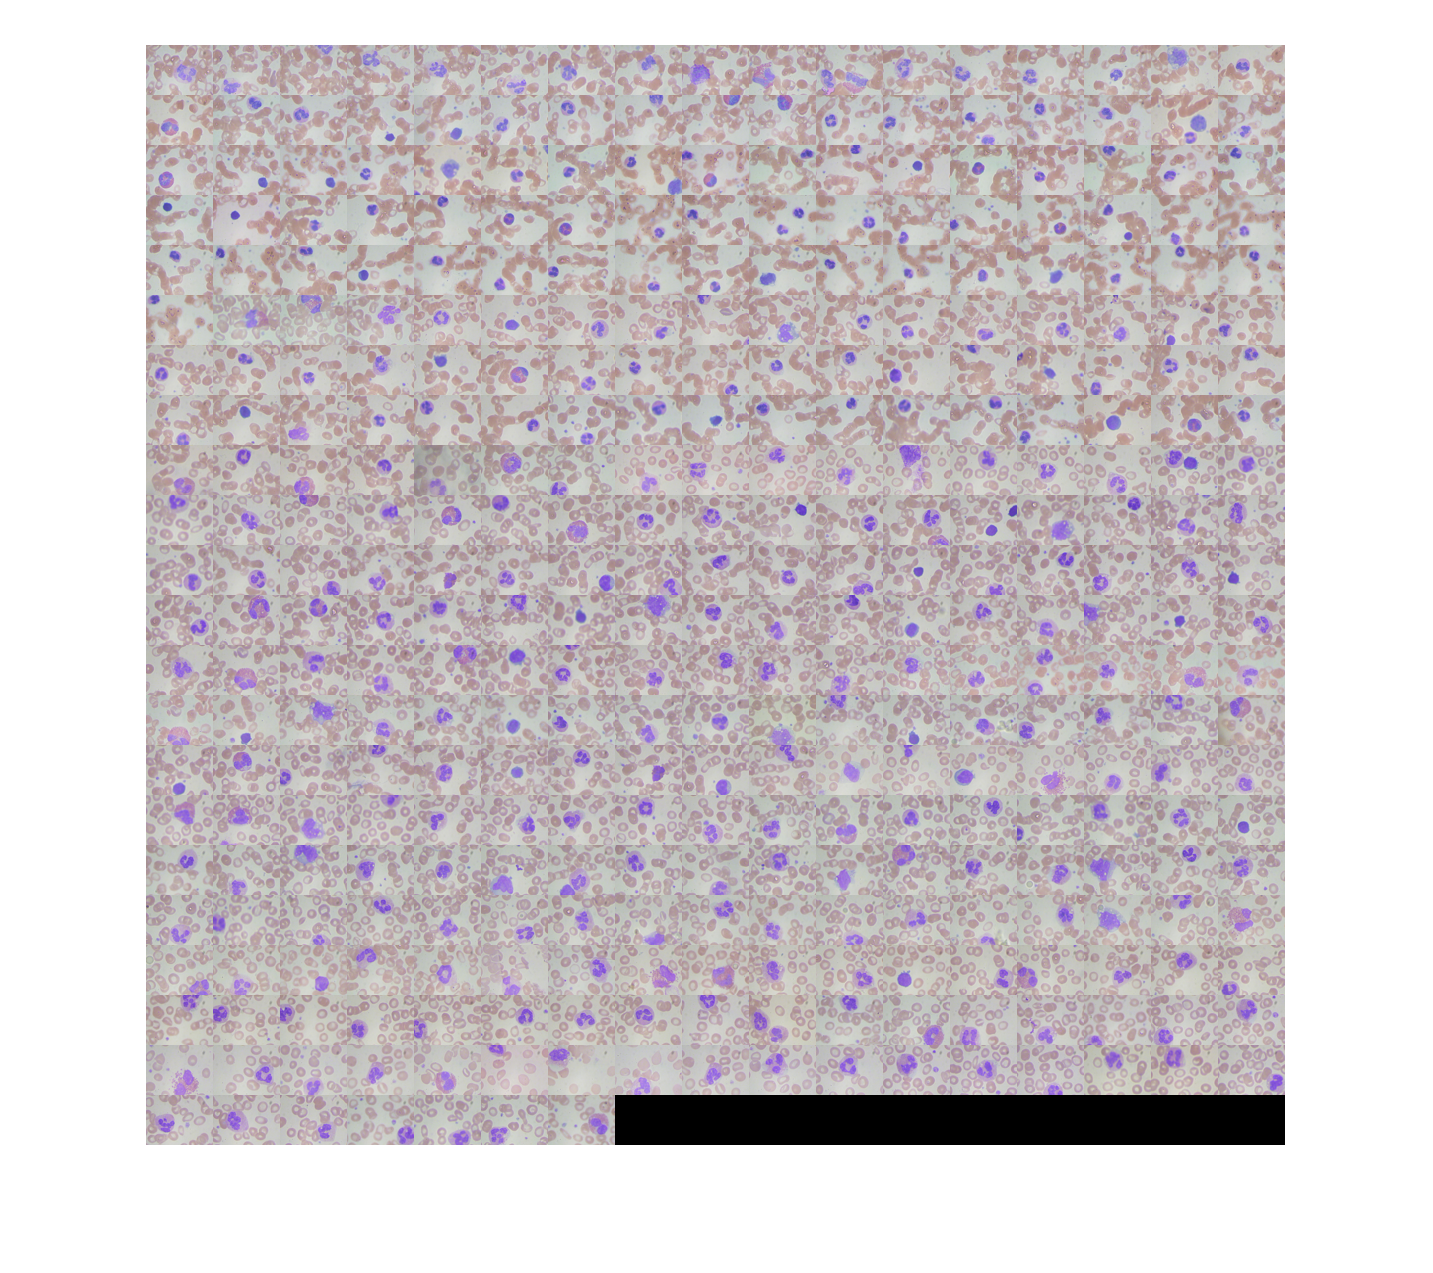

    Irot = imrotate(Ires,90);
    Iadj = imadjust(Irot);

    IDenoise = imfilter(Iadj, avg, 'symmetric'); % Apply averaging filter to the image.     
    BWs(:,:,i) = IDenoise;
end

N =    364


time_serial = toc

**2 CPUs**

tic
parfor i = 1:N
    I = rgb2gray(readimage(imds,1));
    Ires = imresize(I,[480 480]);
    Irot = imrotate(Ires,90);
    Iadj = imadjust(Irot);
    IDenoise = imfilter(Iadj, avg, 'symmetric');  % Apply averaging filter to the image.   
    BWs(:,:,i) = IDenoise;
end
time_parallel = toc
disp(['Parallel computing ' num2str(time_serial/time_parallel) ' times faster'])

time_serial =    6.661136400000000


#### Requirements for parfor-Loops

Because the body of the parfor-loop is executed across multiple instances of MATLAB, there are restrictions on the body of the parfor-loop.

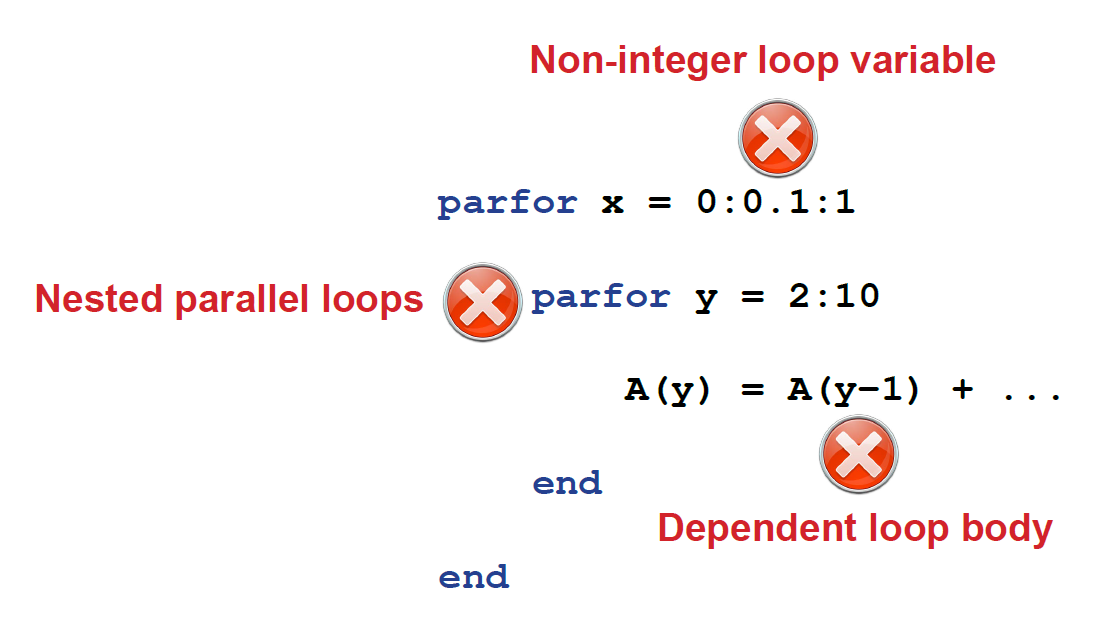 

- The body of the parfor-loop must be **independent**. One iteration of the loop cannot depend on a previous iteration.

- A parfor-loop cannot be **nested** within another parfor-loop. It is, however, acceptable to call a function that uses a parfor-loop from inside the body of another parfor-loop.

- The loop variable for the parfor-loop must consist of **consecutive increasing integer** numbers.

For a more detailed discussion on using parfor-loops, see the [documentation](https://it.mathworks.com/help/parallel-computing/parfor.html).

# GPU Computing

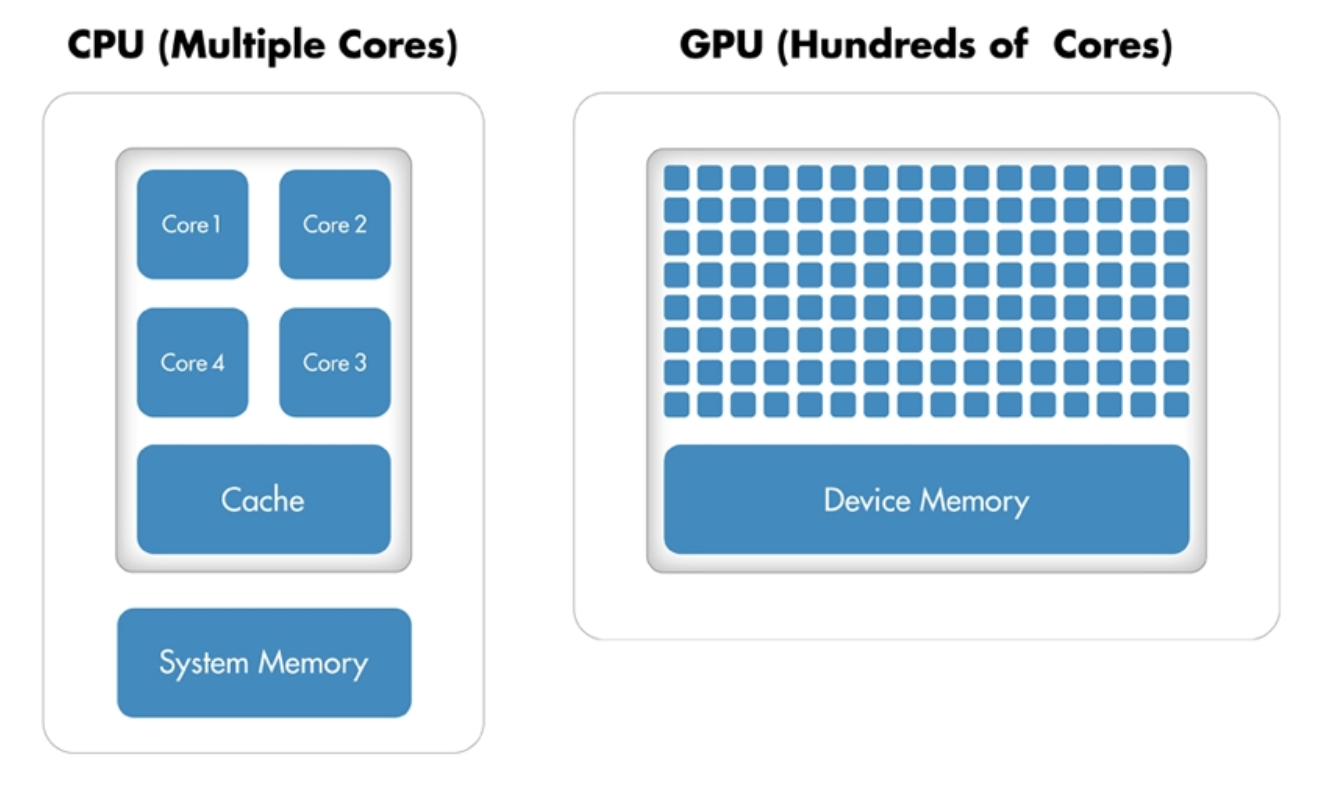

A GPU can accelerate an application if it fits the following criteria: :

- Massively parallel 

- Computationally intensive 

- Algorithm consists of supported functions

#### **Programming with GPUs in MATLAB**

Create regular array:

a = rand(10);

A regular array can be converted to a GPU array using `gpuArray`

A = gpuArray(a);

Perform some calculation:

B = A + 2;

time_parallel =    4.727820600000000


The `gpuArray` can be converted to a regular array using `gather`

b = gather(B);

Parallel computing 1.4089 times faster


whos a A b B

### Parallel-enabled functions and toolboxes

A subset of built-in functions supports the use of gpuArrays. See this [list](https://www.mathworks.com/help/parallel-computing/run-matlab-functions-on-a-gpu.html).

Below, the execution times are compared for performing a fourier transform on some computation on them:

d = gpuDevice
cycles = 30;
CPU = zeros(cycles,1);
GPU = zeros(cycles,1);

**Compute on CPU**

for i = 1:size(CPU,1)
    tic
    A = rand(2000, 'double');
    exp(A * 10 - 5);
    CPU(i) = toc;
end

**Compute on GPU**

for j = 1:size(GPU,1)
    tic

  Name       Size            Bytes  Class       Attributes

  A         10x10                4  gpuArray              
  B         10x10                4  gpuArray              
  a         10x10              800  double                
  b         10x10              800  double                



    A = rand(2000, 'double', 'gpuArray');
    exp(A * 10 - 5);
    wait(gpuDevice)
    GPU(j) = toc;
end

d =   CUDADevice with properties:

                      Name: 'GeForce GPU'
                     Index: 1
         ComputeCapability: '5.0'
            SupportsDouble: 1
             DriverVersion: 11
            ToolkitVersion: 10.100000000000000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.147483647000000e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 1.073741824000000e+09
           AvailableMemory: 360763536
       MultiprocessorCount: 3
              ClockRateKHz: 993000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
            DeviceSelected: 1


**Compare average computing time**

avCPU = mean(CPU)
avGPU = mean(GPU)

**Plot results**

avCPU =    0.128655340000000


avGPU =    0.008793333333333


The average iteration runtime for CPU is 0.12866


The average iteration runtime for GPU is 0.0087933


Mean speedup factor of 15


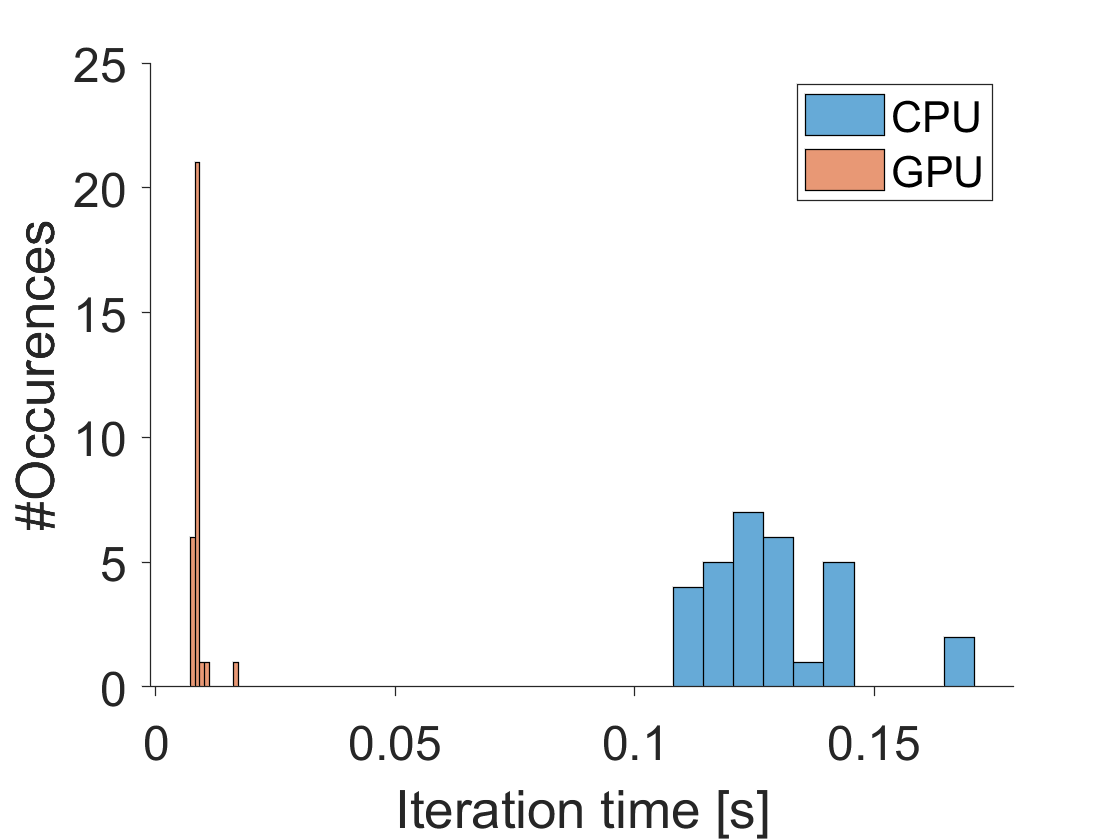

disp(['The average iteration runtime for CPU is ' num2str(avCPU)])
disp(['The average iteration runtime for GPU is ' num2str(avGPU)])
percentDifference = avCPU/avGPU;
fprintf('Mean speedup factor of %i\n',round(percentDifference))
figure
histogram(CPU,10)
hold on
histogram(GPU,10)
legend('CPU','GPU')
set(gca,'TickDir','out','FontSize',18)
box off
xlabel('Iteration time [s]')
ylabel('#Occurences')

### GPU and deep learning

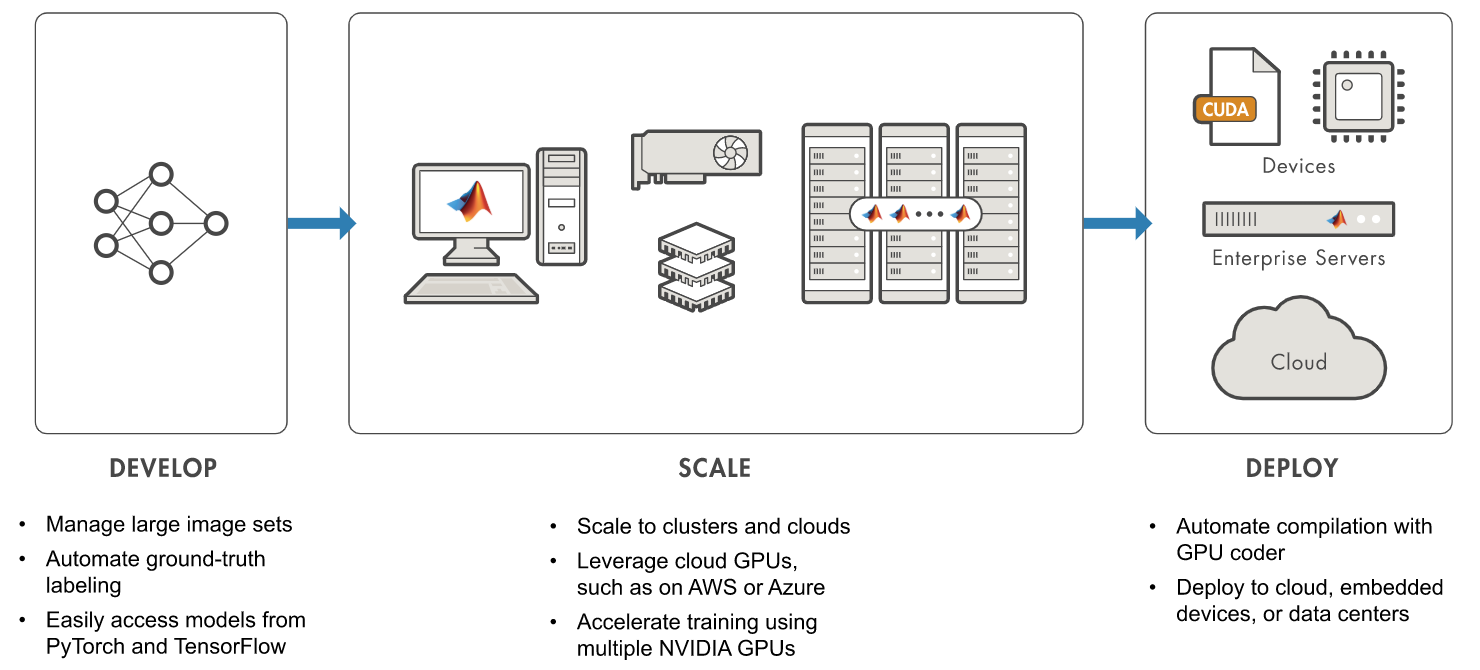

# Summary

**Best practices**

- Pre-allocate memory

- Vectorize

- find bottlenecks with profiler

**Parallel Computing Toolbox**

- Use multiple CPUs

- parfor

- gpuArray

- Many built-in functions have multiple CPU and/or GPU support

**Useful resources:**

More in-depth video on speeding up your MATLAB code

- [https://se.mathworks.com/videos/speeding-up-your-matlab-code-1594323194417.html](https://it.mathworks.com/videos/speeding-up-your-matlab-code-1594323194417.html) 

- Accompanying live script and data on Github

MATLAB Documentation

- [MATLAB ](http://www.mathworks.com/help/matlab/performance-and-memory.html)[Advanced Software Development ](http://www.mathworks.com/help/matlab/performance-and-memory.html)[Performance and  Memory](http://www.mathworks.com/help/matlab/performance-and-memory.html)

- [Parallel Computing Toolbox](http://www.mathworks.com/help/distcomp/index.html)

Parallel and GPU Computing Tutorials

- [https://www.mathworks.com/videos/series/parallel-and-gpu-computing-tutorials-97719.html](https://www.mathworks.com/videos/series/parallel-and-gpu-computing-tutorials-97719.html) 

- [https://se.mathworks.com/videos/parallel-computing-toolbox-overview-69513.html](https://it.mathworks.com/videos/parallel-computing-toolbox-overview-69513.html)

Parallel Computing on the Cloud with MATLAB

- [http://www.mathworks.com/products/parallel-computing/parallel-computing-on-the-cloud/](http://www.mathworks.com/products/parallel-computing/parallel-computing-on-the-cloud/) 